load 'buoydata.mat';
load 'sshdata.mat';
ssh_mean=mean(ssh,3); %create time mean of ssh data

**Figure 1 **

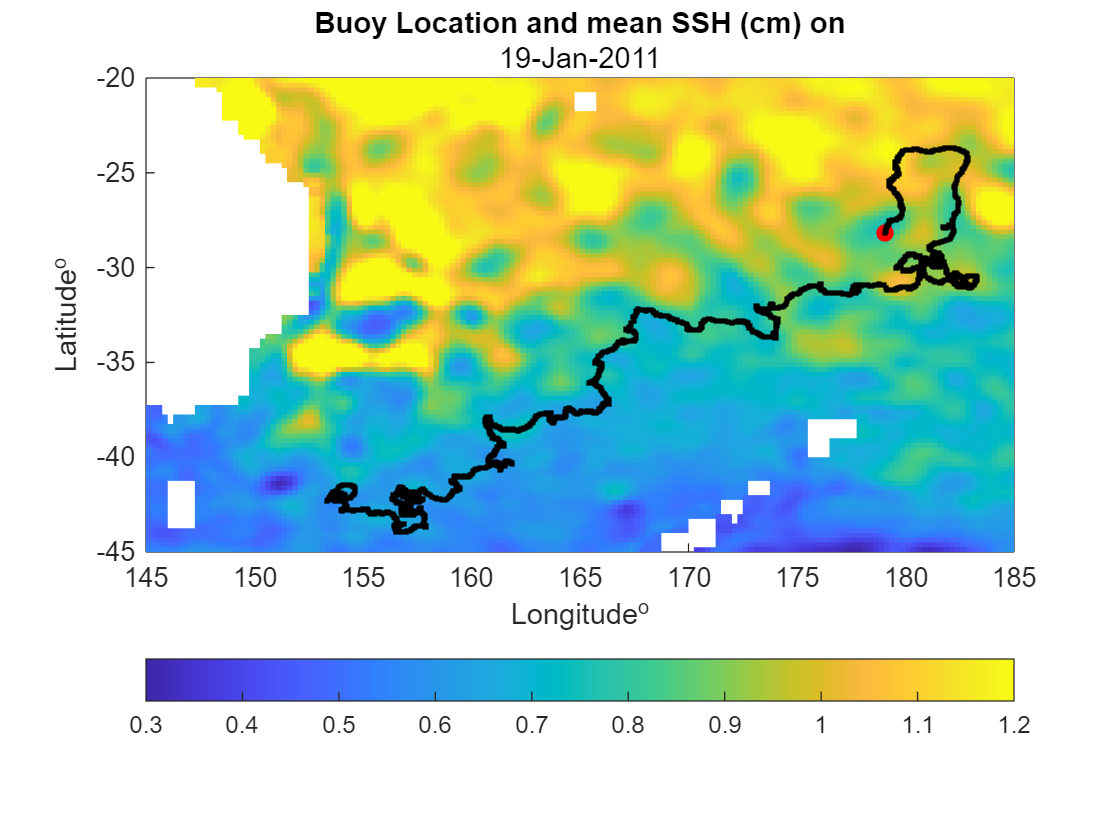

clf
for t=1:length(sshtime)
    pcolor(sshlon,sshlat,squeeze(ssh(:,:,t)))
    shading flat
    clim([0.3,1.2])
    xlabel('Longitude^o')
    ylabel('Latitude^o')
    colorbar('hot')
    title('Buoy Location and mean SSH (cm) on',datestr(sshtime(t)))
    hold on
    ind=find(buoytime==sshtime(t));
    plot(buoylon(ind), buoylat(ind), 'o-', 'color','r', 'markerfacecolor', 'r')
    plot(buoylon(1:ind), buoylat(1:ind), '.', 'color', 'black', 'linewidth', 2) %plots from day 1 up to indexed date
    pause(0.1)
    hold off
end

**Figure 2a (SSH on a Date) and 2b(Mean SSH over -32S)**

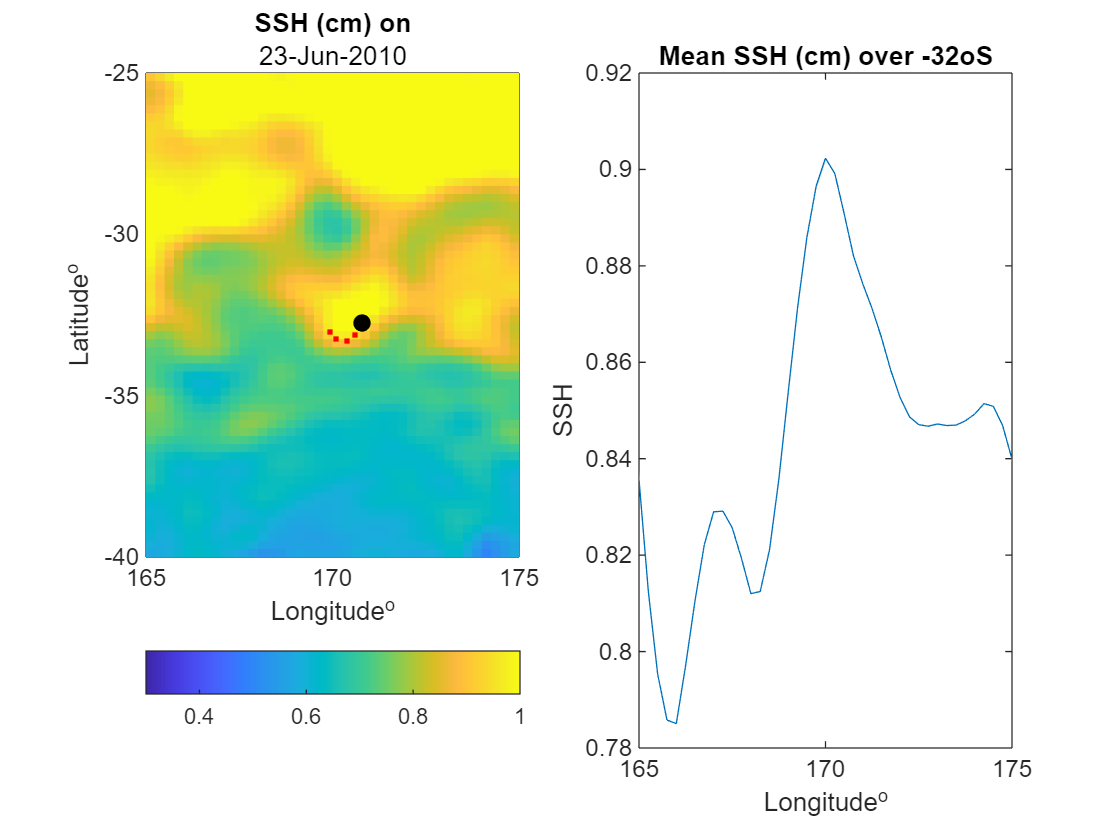

clf 
desiredDate = '2010-06-23';
%daysbefore = [5,10,15,20];
for t = 1:length(sshtime)
    % Convert sshtime(t) to datestring format for comparison
    currentDate = datestr(sshtime(t), 'yyyy-mm-dd');
    
    % Check if the current date matches the desired date with strcmp string
    % compare function. if it returns true, the dates are equal, then plot.
    % 
    subplot(1,2,1)
    if strcmp(currentDate, desiredDate)
        pcolor(sshlon, sshlat, squeeze(ssh(:,:,t)))
        shading flat
        clim([0.3, 1])
        xlabel('Longitude^o')
        ylabel('Latitude^o')
        colorbar('hot')
        title("SSH (cm) on",datestr(sshtime(t)))
        xlim([165 175])
        ylim([-40 -25])
        hold on
        ind = find(buoytime == sshtime(t));
        plot(buoylon(ind), buoylat(ind), 'o-', 'color', 'black', 'markerfacecolor', 'k')
        plot(buoylon(ind-5), buoylat(ind-5), '.', 'color', 'red')
        plot(buoylon(ind-10), buoylat(ind-10), '.', 'color', 'red')
        plot(buoylon(ind-15), buoylat(ind-15), '.', 'color', 'red')
        plot(buoylon(ind-20), buoylat(ind-20), '.', 'color', 'red')
        pause(0.1)
        hold off
    end
    subplot(1,2,2)
    latind=find(sshlat==-32);
    plot(sshlon, ssh_mean(latind,:))
    xlim([165 175])
    title('Mean SSH (cm) over -32oS')
    xlabel('Longitude^o')
    ylabel('SSH')
end

The buoy does make its path around smaller scale changes in sea surface height following pressure gradients while being affected by the coriolis force. Around areas of high sea surface height there would be an outward pressure gradient force (PGF) from the center. As in the southern hemisphere, the Coriolis force would deflect water coming away to the center to the left, forming anti-clockwise eddies. When the buoy is in position near a anti-clockwise, domed eddy, we see that briefly it moves to the left following the anti-clockwise flow (Fig 1.) Other forces besides the PGF and coriolis would have to be responsible for pulling the buoy from the cyclonic eddy and continue it on it's path. But repeatedly in Figure 1 we see the buoy spin anti-clockwise around a high SSH domed eddy.

Highlighting an example around -32S and 170E. Figure 2b. depicts how at around 170E there is an eddy with a higher SSH dome at the center. As said above, the water around this eddy would move anticlockwise. You can see from the snapshot  (Fig. 2a) that the buoy follows this anticlockwise trajectory around the eddy in response to the pressure gradient and coriolis forces. 